# Build a Generative Pretrained Transformer in MATLAB

This demo shows how to build a transformer model to predict the next character in a sequence, based on the works of Shakespeare.

The demo is based on the online lecture [Let's build GPT: from scratch, in code, spelled out](https://www.youtube.com/watch?v=kCc8FmEb1nY) by Andrej Karpathy.

## Data exploration

Download the `sonnets.txt `supporting file. The file `sonnets.txt` contains Shakespeare's sonnets in plain text.

openExample("matlab/AnalyzeTextDataExample",SupportingFile="sonnets.txt",WorkDir=pwd);

Import the data as a character array and tokenize it. The tokenizer converts each character in the raw data to a numeric value so that it can be used as input to a neural network.

rawData = fileread("sonnets.txt");
tokenizer = nanogpt.CharacterTokenizer(rawData);
data = tokenizer.char2tok(rawData);

Partition the data by holding out the last 10% of the data as a validation set.

validationFraction = 0.1;
splitIdx = floor(numel(data)*(1-validationFraction));
dataTrain = data(1:splitIdx);
dataValidation = data(splitIdx+1:end);

Create training and validation datastores with a subsequence length of eight. This means that the model will receive eight tokens at a time during training and use the context of eight tokens to learn to predict future tokens.

subsequenceLength = 8;
dsTrain = nanogpt.SequenceForecastingDatastore(dataTrain, subsequenceLength, tokenizer.VocabSize);
dsValidation = nanogpt.SequenceForecastingDatastore(dataValidation, subsequenceLength, tokenizer.VocabSize);

Preview the first few elements of the training set as characters.

tbl = dsTrain.preview();
tokenizer.tok2char(tbl.predictors)

ans = 8×8 char array
    '  The mo'
    'k,↵  As '
    'd often '
    'rofan'd,'
    ' set dow'
    'to brief'
    'what is''
    'id proce'


tokenizer.tok2char(tbl.responses)

ans = 8×8 char array
    ' The mos'
    ',↵  As t'
    ' often i'
    'ofan'd, '
    'set down'
    'o brief '
    'hat is't'
    'd procee'


Create minibatchqueues for the training and validation data.

miniBatchSize = 128;
mbqTrain = minibatchqueue(dsTrain, ...
    MinibatchSize=miniBatchSize, ...
    MiniBatchFcn=@(X,T) preprocessMinibatch(X,T), ...
    MiniBatchFormat={'BTC', 'BTC'});
mbqValidation = minibatchqueue(dsValidation, ...
    MinibatchSize=miniBatchSize, ...
    MiniBatchFcn=@(X,T) preprocessMinibatch(X,T), ...
    MiniBatchFormat={'BTC', 'BTC'});

## Train Bigram Model

As a baseline, train a bigram model, which guesses the next letter based only on the one immediately before it.

Define the network

bigramNet = dlnetwork( ...
    [ ...
    sequenceInputLayer(1), ...
    wordEmbeddingLayer(tokenizer.VocabSize, tokenizer.VocabSize), ...
    softmaxLayer()]);

Before training the network, compute the loss for a minibatch of data to show the performance of a completely random model.

[X,T] = mbqTrain.next();
loss = dlfeval(@nanogpt.modelLoss, bigramNet, X, T)

loss =   1×1 single gpuArray dlarray

    4.1272


The expected performance of a random model is

$-\log \frac{1}{n_\mathrm{vocab}$.

Compute this value for comparison.

expectedRandomLoss = -log(1/tokenizer.VocabSize)

expectedRandomLoss = 4.1271

Generate 100 new tokens from the model.

numNewChars = 100;
dsValidation.MiniBatchSize = 1;
tbl = dsValidation.preview();
context = tbl.predictors;
predictFromModel(bigramNet, context, numNewChars, tokenizer)

ans =     'f.
     e-BRuHNFBxoOL'xgPTjt?)OYp'F?'PiwfwLGwf
      fT
     JMJIDFV-nDbVsqWUhlFDAkOh(UHFUogp)fcyjA-MW)YHYIDNXNwhH,'


Train the model for 2000 iterations.

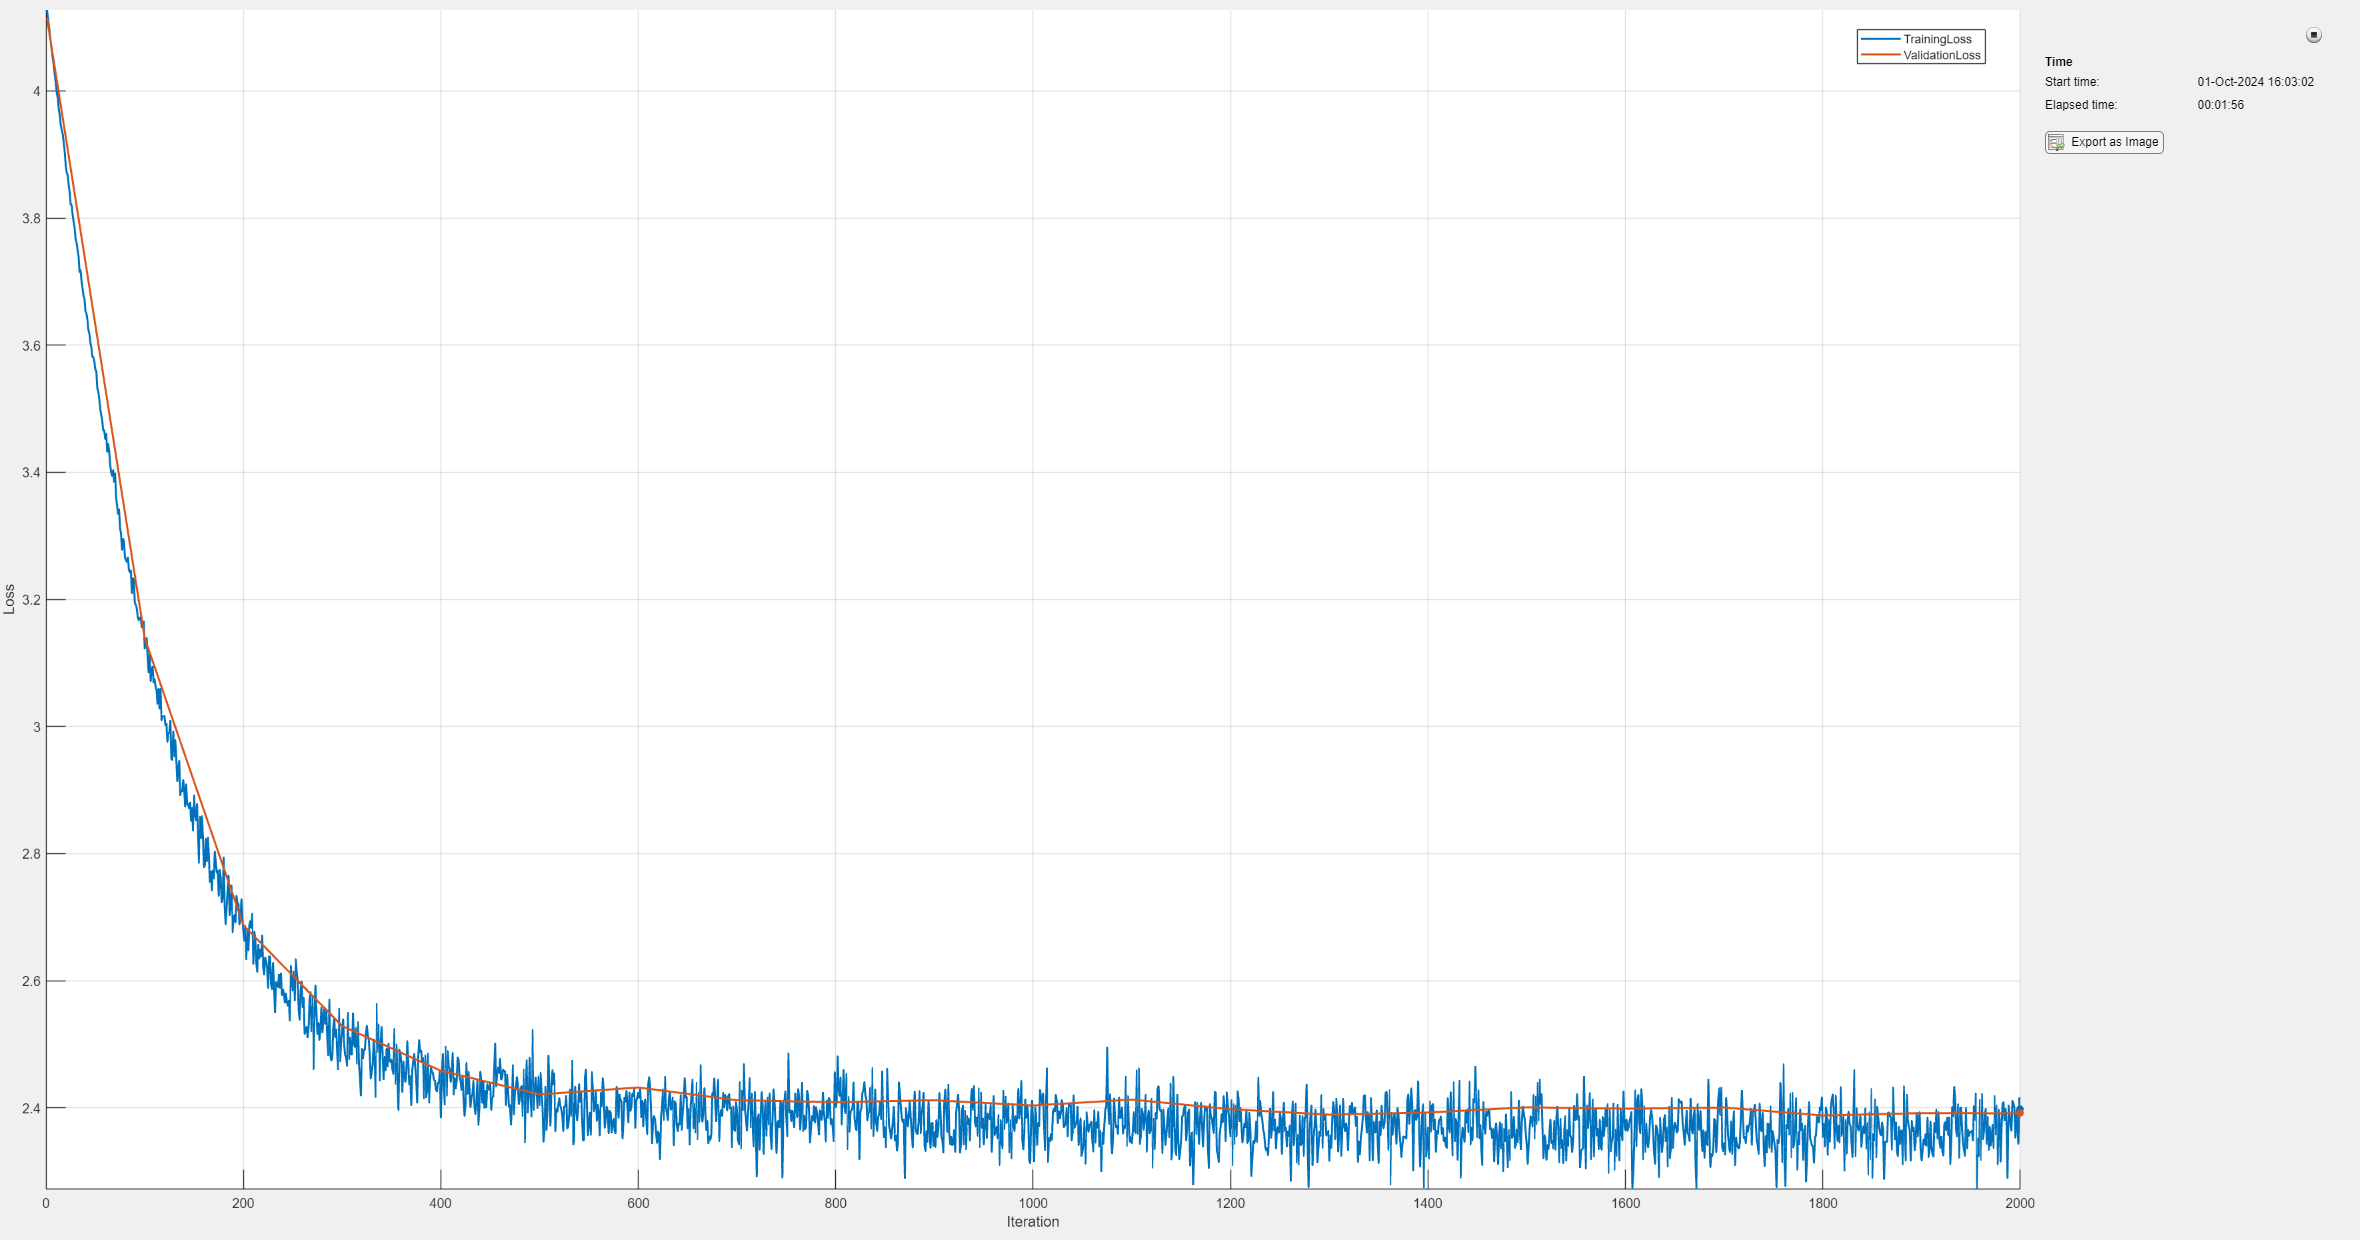

numIterations = 2000;
validationFrequency = 100;
numValidationIters = 20;
learnRate = 1e-2;

bigramNet = nanogpt.train(bigramNet, mbqTrain, mbqValidation, ...
    LearnRate=learnRate, ...
    NumIterations=numIterations, ...
    ValidationFrequency=validationFrequency, ...
    NumValidationIters=numValidationIters);

Use the trained model to predict 500 new tokens.

numNewChars = 500;
dsValidation.MiniBatchSize = 1;
tbl = dsValidation.preview();
context = tbl.predictors;
disp(predictFromModel(bigramNet, context, numNewChars, tokenizer))

tont toe's y Siqu;
 hing u t Wir 'd, minecy Why Ma hong the rtouth  tok!
 Fr n  t and
 ho ir Thele my  iee:
 ours.
 CV
 g bjalithaghy fotha enonad ince t Whitam  Whooess oigerd ne miseaunconofty w;
 thed in then hor al'de  ne Fovaso greit My sthe ink I lie,
 n htthenveld s   out tomoute thincethat An nourokl ththongDupe ilde Buldenol,
 h os aul,Why me r oret Yonchowale n ct the  XX?
 farlf teke atyermeallo.
 p my ano ink  me, arliow t n tinaillisaste,

 ts inkig Of ce So t in mmethixprt For tou,


## Add Self-Attention

The bigram model uses only the previous token to predict the next token. With self-attention, the network can use all previous tokens in a sample to determine the probabilities for the output. Build a self-attention head out of basic layers.

outputSize = tokenizer.VocabSize;
numKeyChannels = 32;

layers = [
    functionLayer(@(x,y) nanogpt.batchmtimes(x,"none",y,"transpose"),Name="mtimes_KQ")
    functionLayer(@(x) x/sqrt(numKeyChannels), Name="scale")];

% Add a causal mask to prevent the network "cheating" by looking ahead
layers = [layers
    functionLayer(@(x) nanogpt.applyCausalMask(x),Name="mask")];

layers = [layers
    softmaxLayer
    functionLayer(@(x,y) nanogpt.batchmtimes(x,"none",y,"none"),Name="mtimes_KQV")
    fullyConnectedLayer(outputSize,Name="fc_out")];

attentionNet = dlnetwork(layers,Initialize=false);

% Add the keys, queries and values
queryLayer = fullyConnectedLayer(numKeyChannels,Name="fc_queries");
keyLayer = fullyConnectedLayer(numKeyChannels,Name="fc_keys");
valueLayer = fullyConnectedLayer(numKeyChannels,Name="fc_values");
attentionNet = addLayers(attentionNet,queryLayer);
attentionNet = addLayers(attentionNet,keyLayer);
attentionNet = addLayers(attentionNet,valueLayer);
% Connect them up
attentionNet = connectLayers(attentionNet,"fc_queries","mtimes_KQ/in1");
attentionNet = connectLayers(attentionNet,"fc_keys","mtimes_KQ/in2");
attentionNet = connectLayers(attentionNet,"fc_values","mtimes_KQV/in2");

Plot the network to view its structure

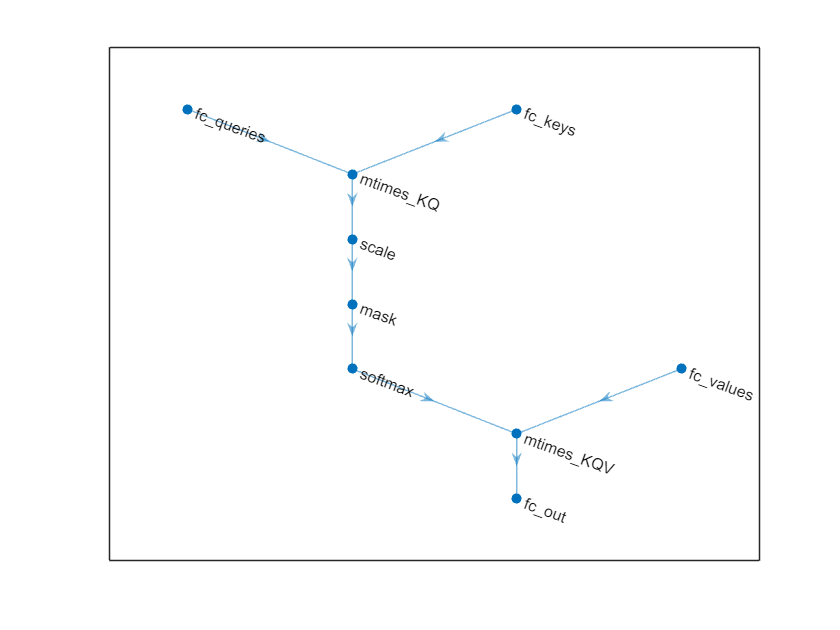

plot(attentionNet)

Connect this attention head up to the bigram network, with the following modifications:

- Change the number of embedding dimensions from vocabSize to 32

- Add a fully connected layer after the wordEmbeddingLayer to change the number of channels to match the vocab size

- Move the softmax layer to after the attention head

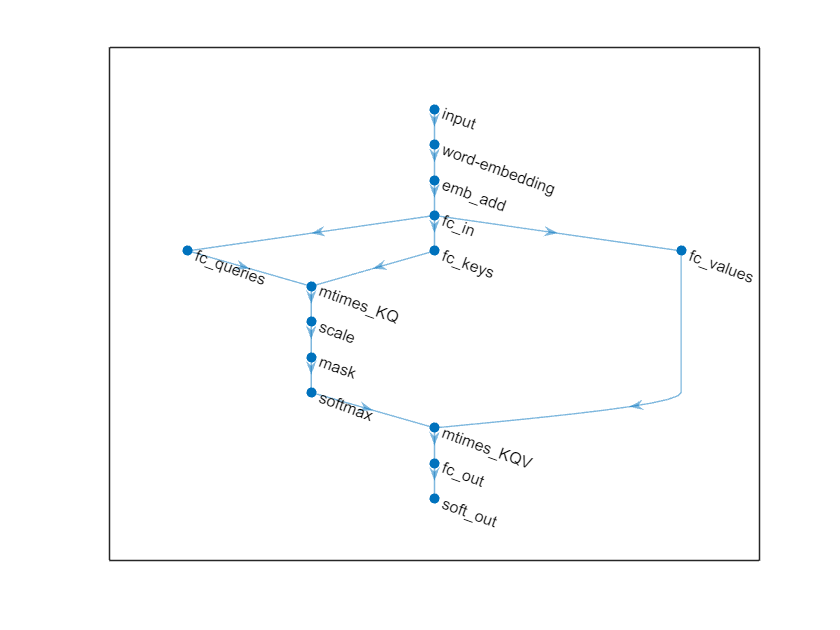

numChannels = 1;
embeddingDimension = 32;
inLayers = [sequenceInputLayer(numChannels,Name="input"), ...
    wordEmbeddingLayer(embeddingDimension,tokenizer.VocabSize), ...
    additionLayer(2, Name="emb_add"), ...
    fullyConnectedLayer(tokenizer.VocabSize, Name="fc_in"), ...
];
attentionNet = addLayers(attentionNet,inLayers);
attentionNet = connectLayers(attentionNet,"fc_in","fc_queries");
attentionNet = connectLayers(attentionNet,"fc_in","fc_keys");
attentionNet = connectLayers(attentionNet,"fc_in","fc_values");
attentionNet = addLayers(attentionNet,softmaxLayer(Name="soft_out"));
attentionNet = connectLayers(attentionNet,"fc_out","soft_out");

plot(attentionNet)

Attention is a permutation-invariant operation, so the positions in the sequence must be encoded into the input to the attention head or the network will not have any information about where the tokens appear in the input.

Add a second branch to the network to apply position embedding and add it to the output of the word embedding layer.

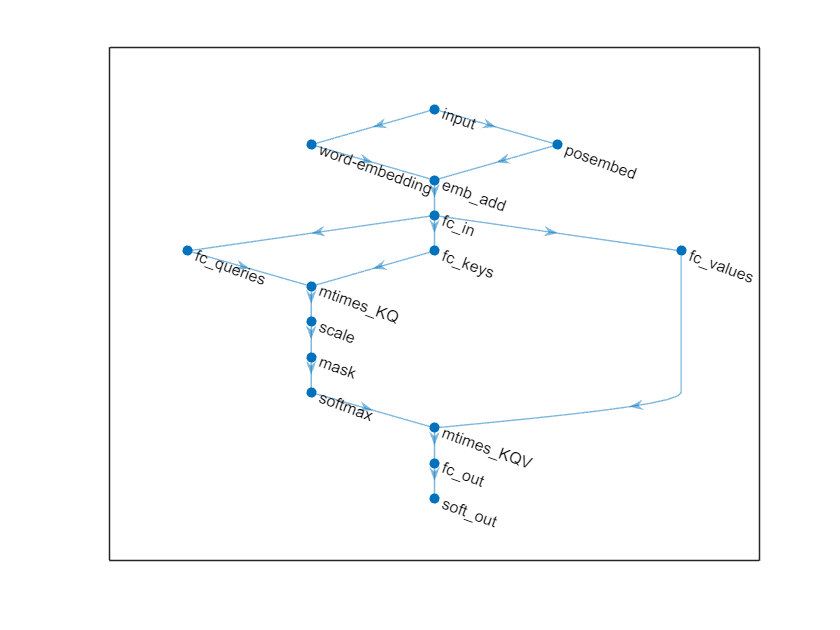

attentionNet = attentionNet.addLayers(positionEmbeddingLayer(embeddingDimension, subsequenceLength, Name="posembed"));
attentionNet = attentionNet.connectLayers("input", "posembed");
attentionNet = attentionNet.connectLayers("posembed", "emb_add/in2");
attentionNet = attentionNet.initialize();

plot(attentionNet)

analyzeNetwork(attentionNet)

Train the network for 5000 iterations.

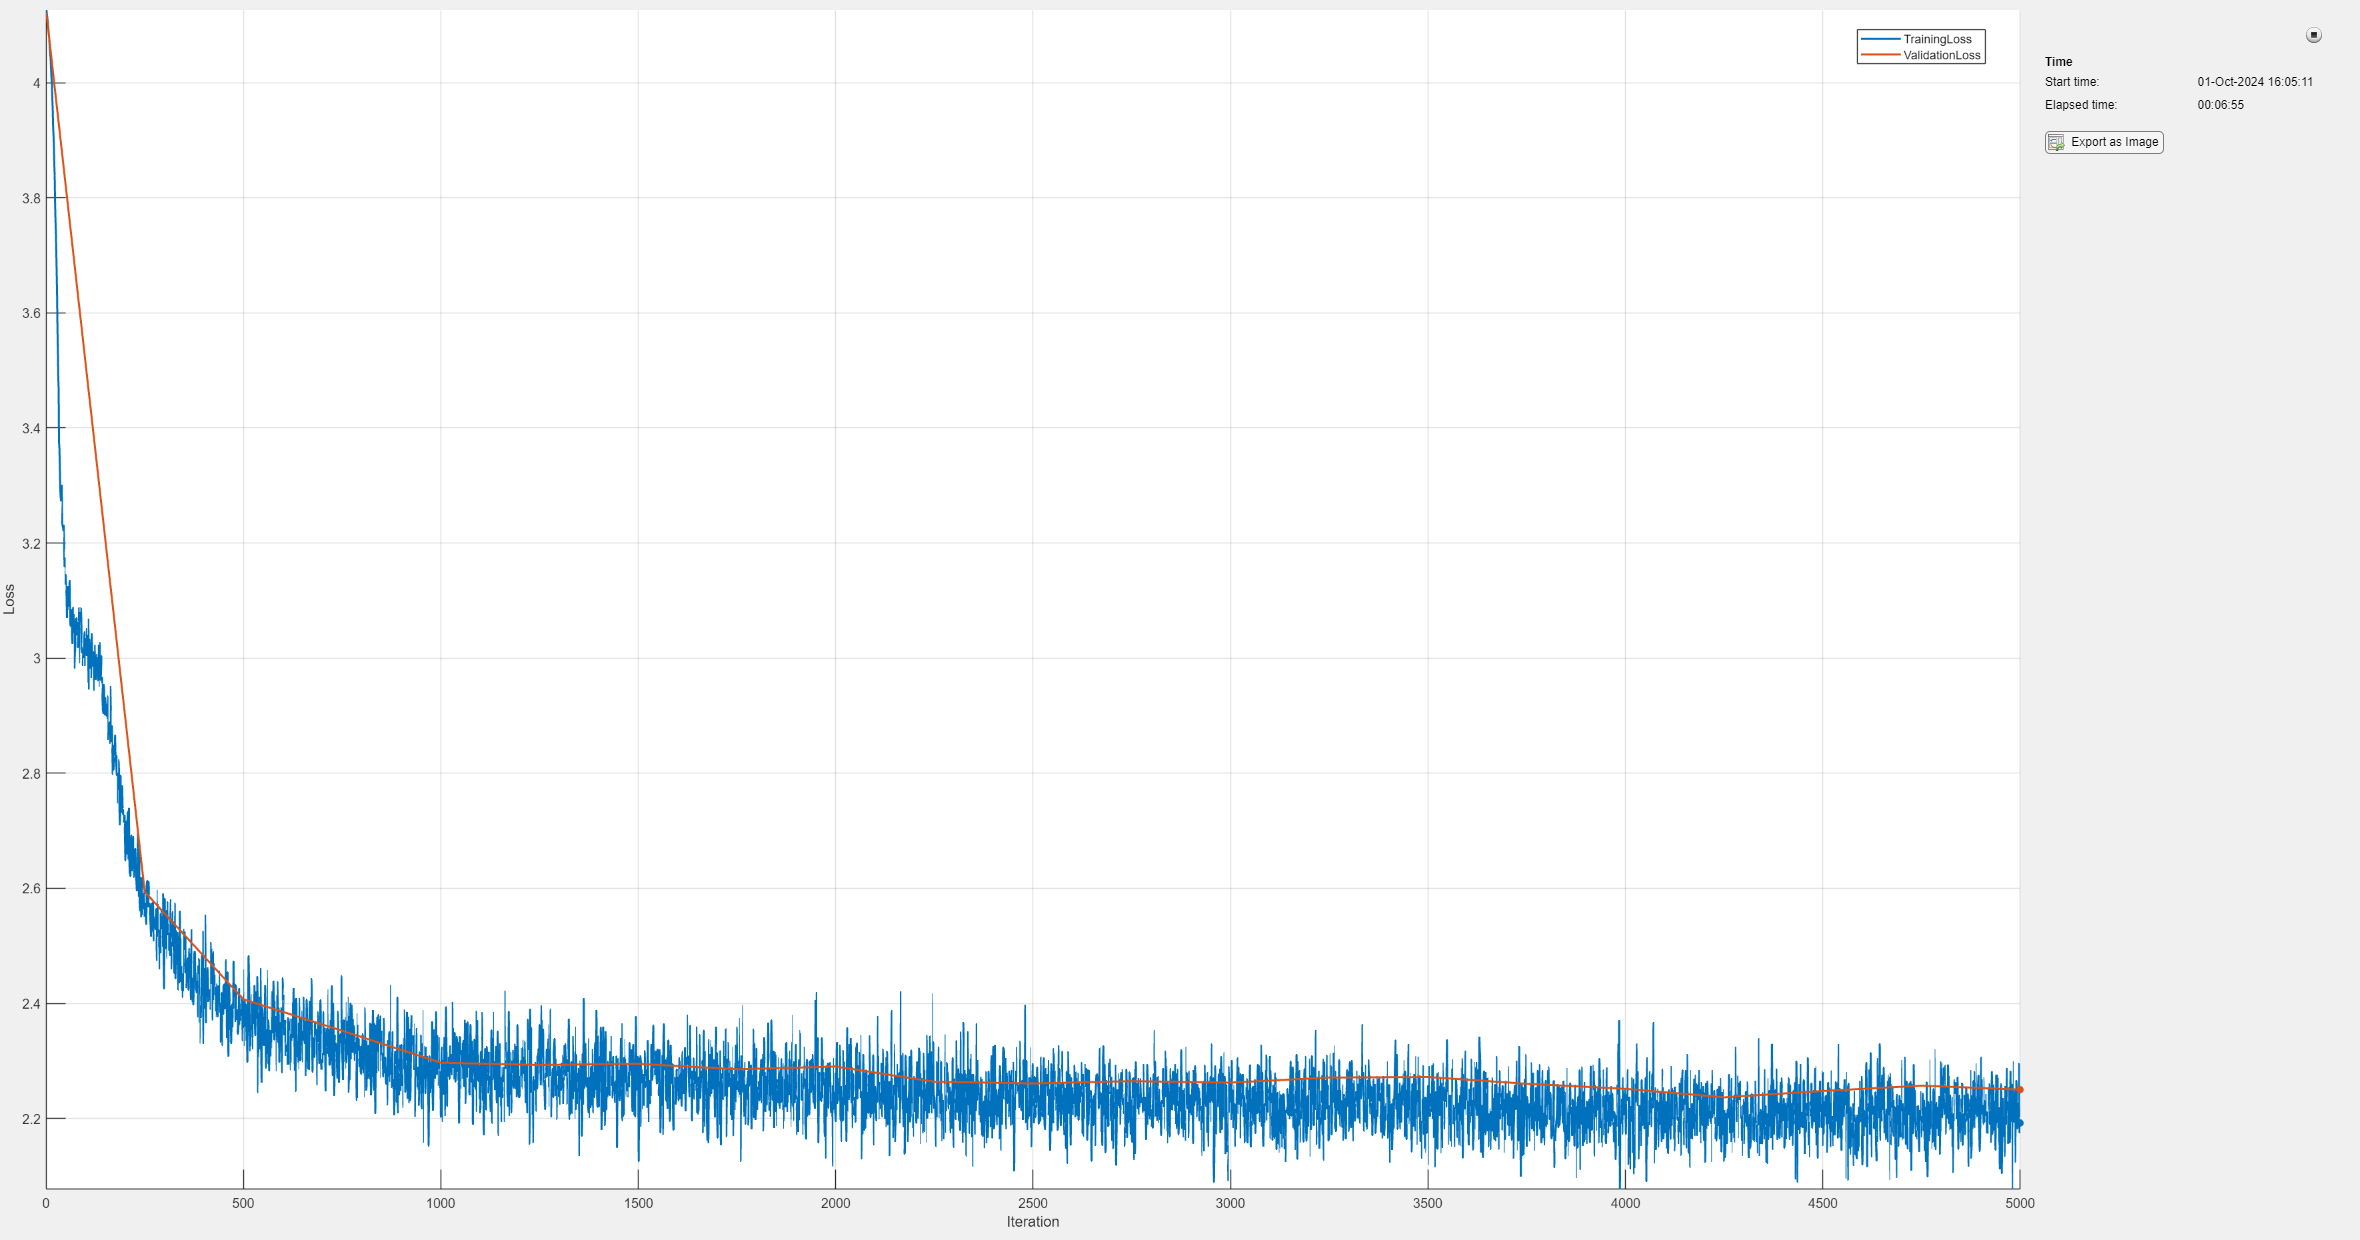

numIterations = 5000;
validationFrequency = 250;
numValidationIters = 20;
learnRate = 1e-3;

attentionNet = nanogpt.train(attentionNet, mbqTrain, mbqValidation, ...
    LearnRate=learnRate, ...
    NumIterations=numIterations, ...
    ValidationFrequency=validationFrequency, ...
    NumValidationIters=numValidationIters);

Generate 500 tokens from the trained network.

numNewChars = 500;
dsValidation.MiniBatchSize = 1;
tbl = dsValidation.preview();
context = tbl.predictors;
disp(predictFromModel(attentionNet, context, numNewChars, tokenizer))

sok,
 Risi chon Dtry ete scove e dadis lat aimprarmind arte by omme at:

   As hore bule,
  Ongrce:
   May mblove.
 


  Evoupeall f thanke,
   Whar sothangin.
   S lad l ds ampirmith whayurcal wailee ghild, moughety bay sye s th'se yo chyowre pelolver.
  Smy XeI

   Whiet:
   Sharo.
  Whimid outy ptmice,
  Wher.
  Whermescon qupe-zer e Noorut Thimpig bory oulle ark
  I ithte lil sp thulifo fraik tis how and thedart besisht,
  Fort ho thyo ralve, worue ealt?
   Ofr in be besidst,
   tess'd bess 


## Multi-head Attention

Currently the network uses a single self-attention head. Using multiple heads can improve preformance, because each head can specialize, computing different correlations between tokens.

Using the self-attention layer from the Deep Learning Toolbox we can straightforwardly add multiple heads.

numChannels = 1;
embeddingDimension = 32;
numHeads = 4;
numKeyChannels = embeddingDimension;

multiHeadAttentionNet = dlnetwork([ ...
    sequenceInputLayer(numChannels, Name="input"), ...
    wordEmbeddingLayer(embeddingDimension,tokenizer.VocabSize), ...
    additionLayer(2, Name="emb_add"), ...
    fullyConnectedLayer(tokenizer.VocabSize), ...
    selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal"), ...
    softmaxLayer], Initialize=false);
multiHeadAttentionNet = multiHeadAttentionNet.addLayers(positionEmbeddingLayer(embeddingDimension, subsequenceLength, Name="posembed"));
multiHeadAttentionNet = multiHeadAttentionNet.connectLayers("input", "posembed");
multiHeadAttentionNet = multiHeadAttentionNet.connectLayers("posembed", "emb_add/in2");
multiHeadAttentionNet = multiHeadAttentionNet.initialize();

Train the network for 5000 iterations and generate 500 new tokens.

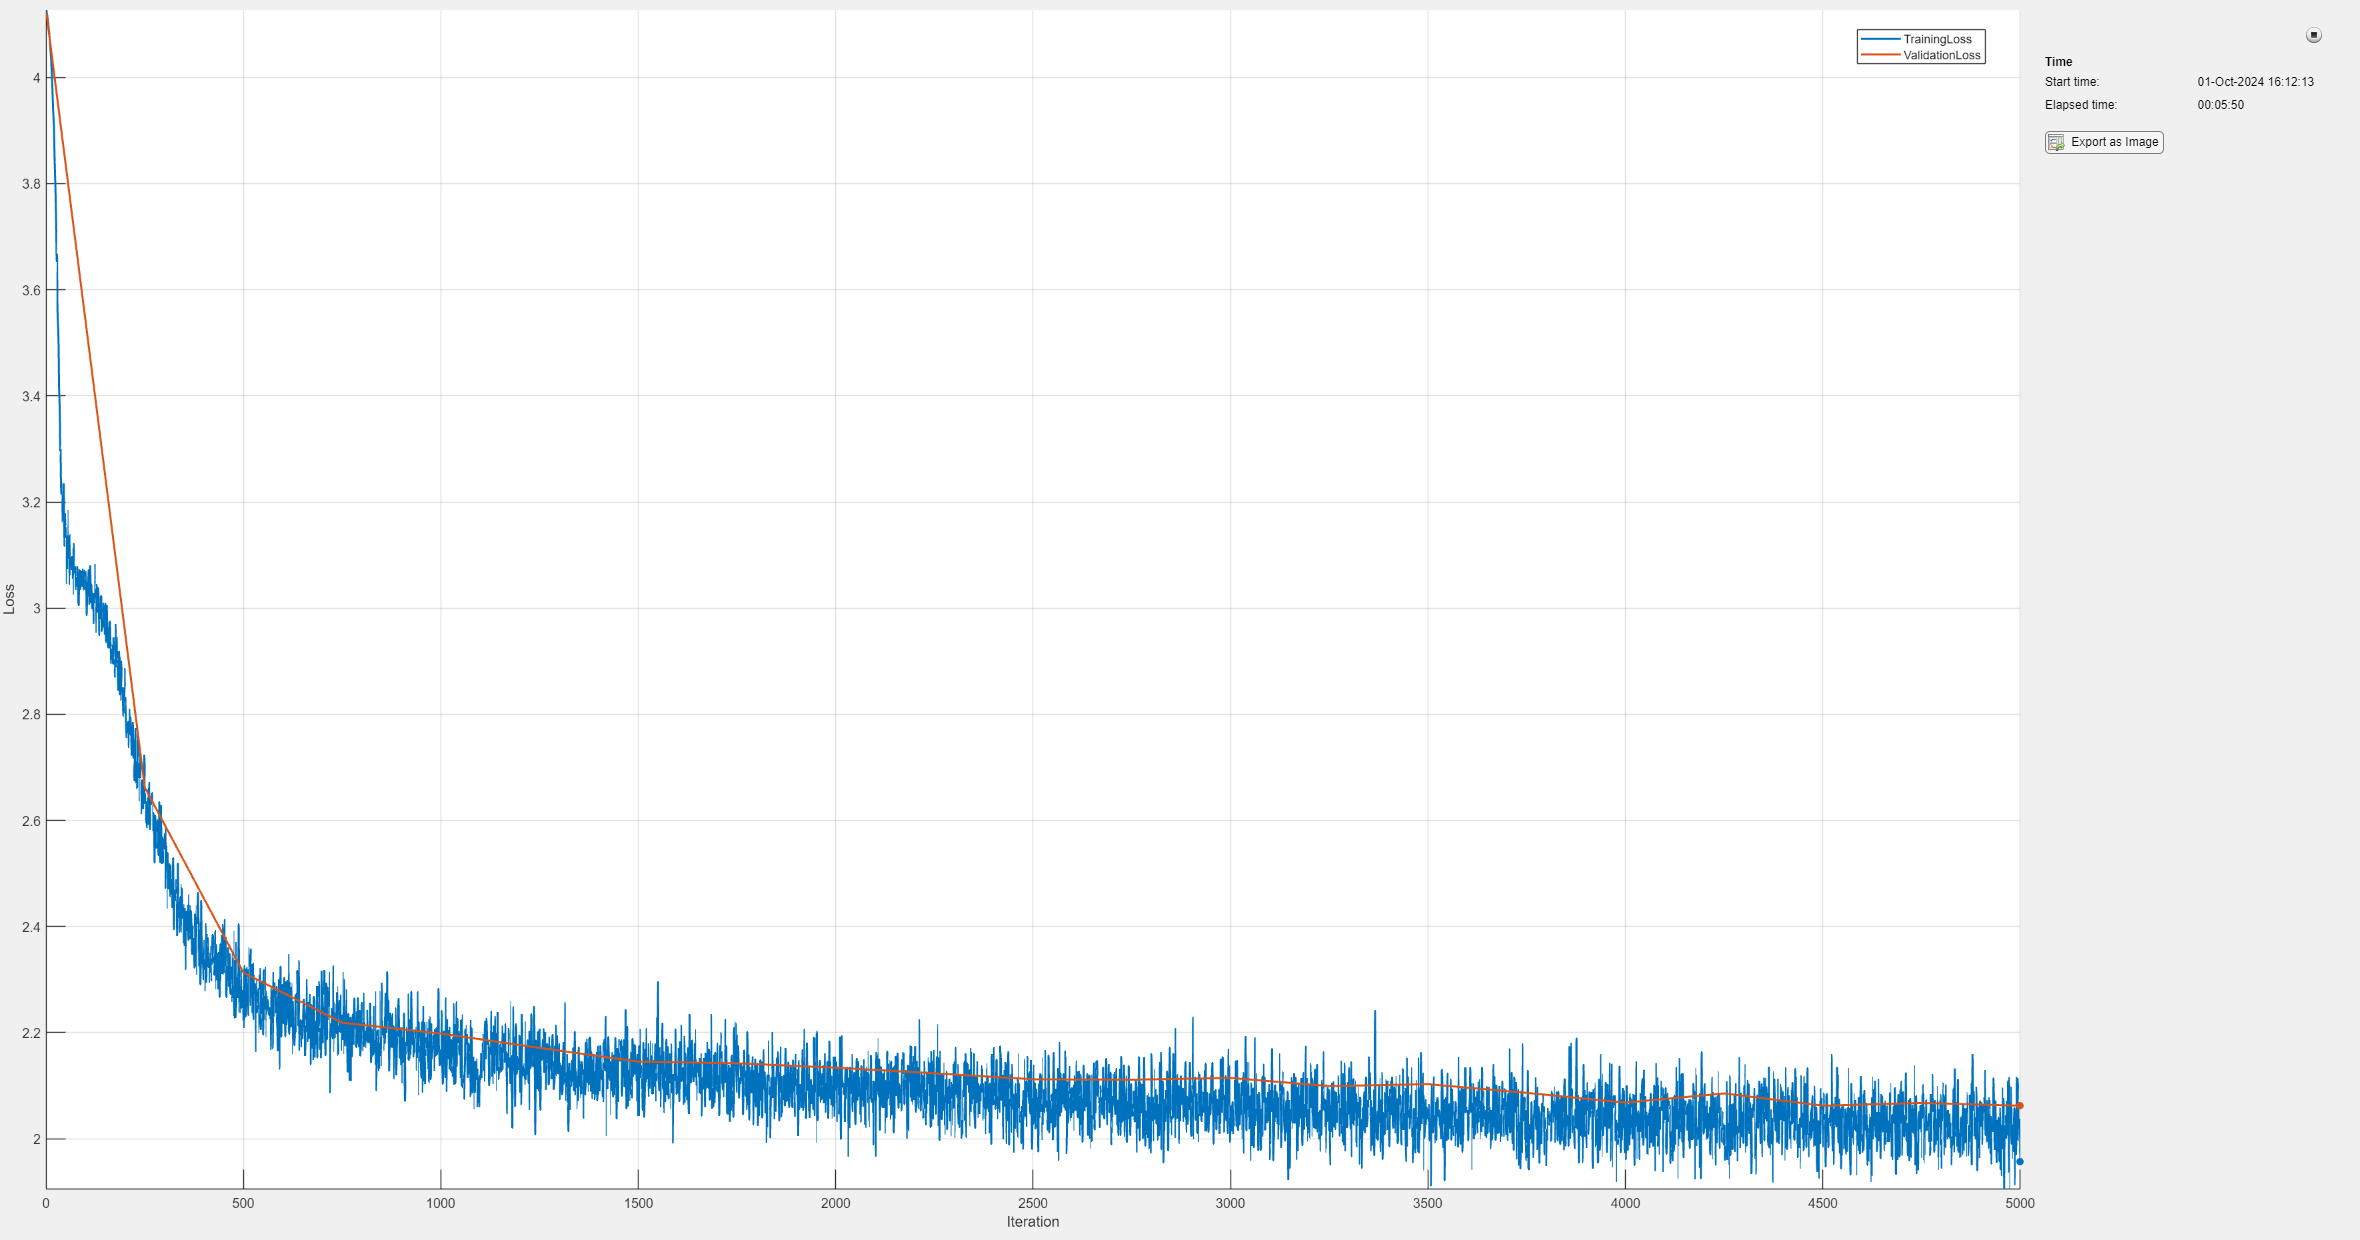

numIterations = 5000;
validationFrequency = 250;
numValidationIters = 20;
learnRate = 1e-3;

multiHeadAttentionNet = nanogpt.train(multiHeadAttentionNet, mbqTrain, mbqValidation, ...
    LearnRate=learnRate, ...
    NumIterations=numIterations, ...
    ValidationFrequency=validationFrequency, ...
    NumValidationIters=numValidationIters);

numNewChars = 500;
dsValidation.MiniBatchSize = 1;
tbl = dsValidation.preview();
context = tbl.predictors;
disp(predictFromModel(multiHeadAttentionNet, context, numNewChars, tokenizer))

ng gat hus.
  Wimpes nerveoreal I
  And dopee shave
  Thightouwer youe hume, unquiong to con mich this se arut gre ast rred,
    Yeat of hel bey bevee ast'd
  Am neacick's gopormp.
  To I longs the top cad dalssss shin.

  Lod nasss hint.
  CXXXIII
   Thoult warunk ompefantigh untt,
  Buen ben thumme hat whis myourn cet fhatoh posge,
  Thow shs mundermuts dod cas I nutthou 'Or to bray sist hist, Les you se'd sporre the.
  In con'd;
  'The mouptar myou ber ipess ade sal speacy oo bud naptul'd exg


The network can be improved further by adding a fully connected layer and a relu layer after the self-attention layer, to process the outputs of the attention heads.

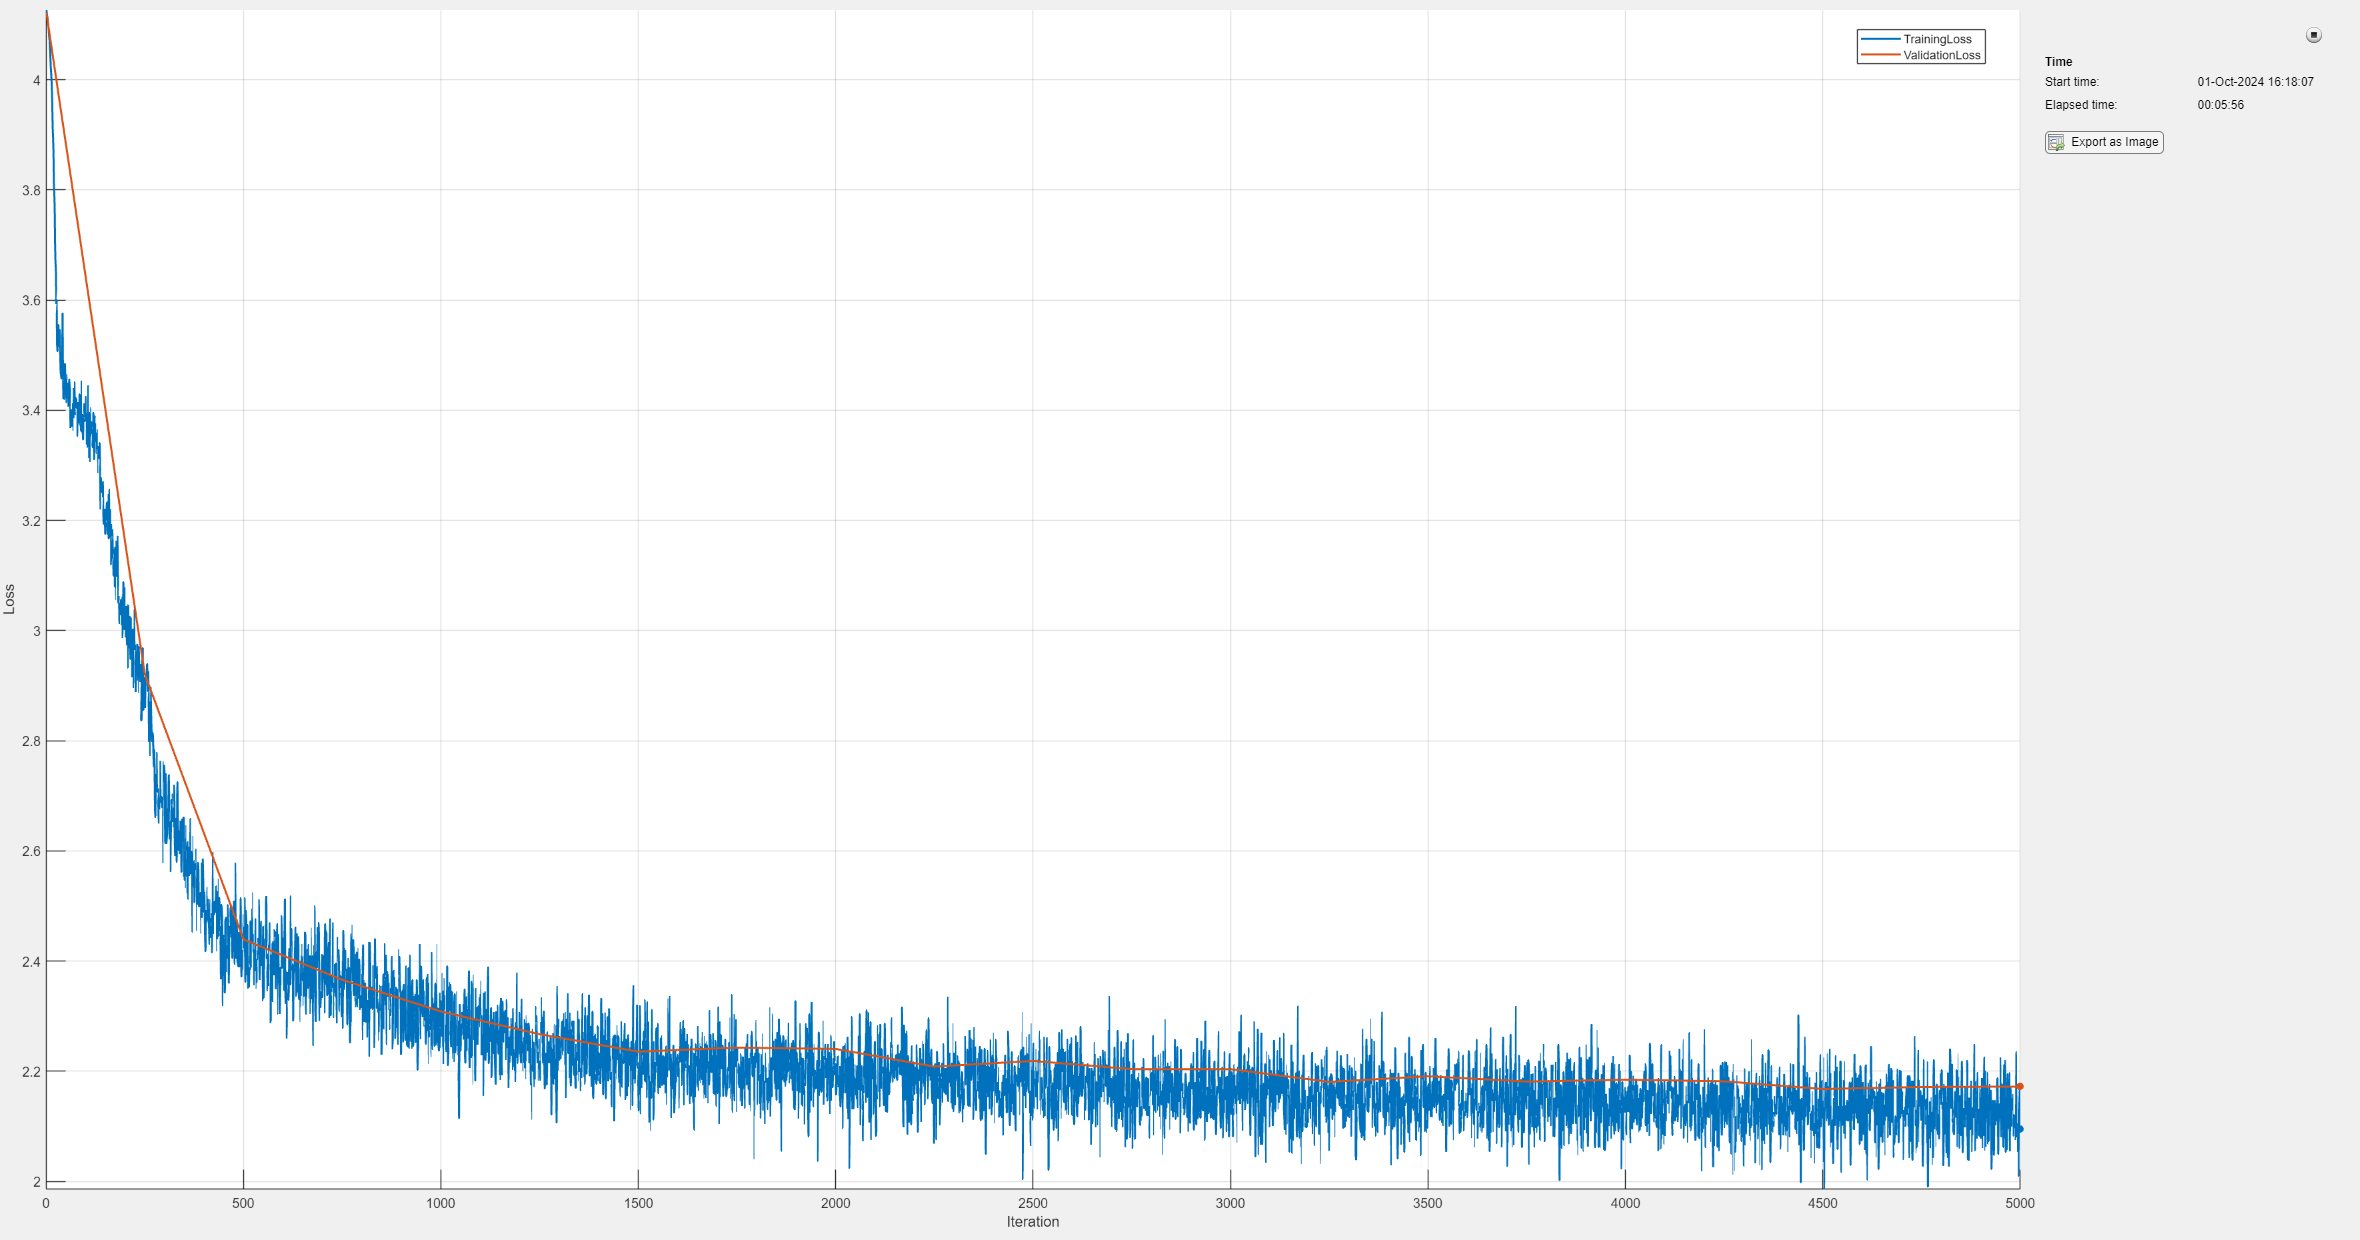

multiHeadAttentionNet2 = dlnetwork([ ...
    sequenceInputLayer(numChannels, Name="input"), ...
    wordEmbeddingLayer(embeddingDimension,tokenizer.VocabSize), ...
    additionLayer(2, Name="emb_add"), ...
    fullyConnectedLayer(tokenizer.VocabSize), ...
    selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal"), ...
    fullyConnectedLayer(tokenizer.VocabSize), ...
    reluLayer, ...
    softmaxLayer], Initialize=false);
multiHeadAttentionNet2 = multiHeadAttentionNet2.addLayers(positionEmbeddingLayer(embeddingDimension, subsequenceLength, Name="posembed"));
multiHeadAttentionNet2 = multiHeadAttentionNet2.connectLayers("input", "posembed");
multiHeadAttentionNet2 = multiHeadAttentionNet2.connectLayers("posembed", "emb_add/in2");
multiHeadAttentionNet2 = multiHeadAttentionNet2.initialize();

multiHeadAttentionNet2 = nanogpt.train(multiHeadAttentionNet2, mbqTrain, mbqValidation, ...
    LearnRate=learnRate, ...
    NumIterations=numIterations, ...
    ValidationFrequency=validationFrequency, ...
    NumValidationIters=numValidationIters);


tbl = dsValidation.preview();
context = tbl.predictors;
disp(predictFromModel(multiHeadAttentionNet2, context, numNewChars, tokenizer))

rLri;
  No tu-ray
  Of thezen sher shanUpo aH ih (toth seart thar cat )s Whoadlests not,
  und,
  LoX

  pumst chin;
  swheiitonNo lolX

   my of icYou eay,
   I hou delich fif chey heise eand lis xpy them in andous hend prontell, eauMile,
    For is )s finpppss a to and winuWhy dear I a
  inzecee hoalli:
  (athe nelfor thies of thy ipst'
  CXXII

  To yose aJunt me tow of this'd
  And tairJert,
  liOrs mill rit .

  No sid, stine peea
  That soresto lour so fam'd.


  son, thy the ly mith the R


## Making the network deeper

Make the network deeper by repeating attention blocks. Just repeating the blocks tends to give a network that trains poorly due to vanishing gradients. To prevent this, add layer normalization and skip connections.

deeperNet = dlnetwork([ ...
    sequenceInputLayer(numChannels, Name="input"), ...
    wordEmbeddingLayer(embeddingDimension,tokenizer.VocabSize), ...
    additionLayer(2, Name="emb_add"), ...
    fullyConnectedLayer(tokenizer.VocabSize, Name="emb_fc")], Initialize=false);
deeperNet = deeperNet.addLayers(positionEmbeddingLayer(embeddingDimension, subsequenceLength, Name="posembed"));
deeperNet = deeperNet.connectLayers("input", "posembed");
deeperNet = deeperNet.connectLayers("posembed", "emb_add/in2");
lastLayerName = "emb_fc";

numAttnBlocks = 3;
for ii = 1:numAttnBlocks
    attnBlock = attentionBlock(numHeads, numKeyChannels, tokenizer.VocabSize, ii);
    deeperNet = deeperNet.addLayers(attnBlock);
    deeperNet = deeperNet.connectLayers(lastLayerName, "attn_sa_"+ii);
    % Create skip connections
    deeperNet = deeperNet.connectLayers(lastLayerName, "attn_add1"+ii+"/in2");
    deeperNet = deeperNet.connectLayers("attn_norm1_"+ii, "attn_add2"+ii+"/in2");
    lastLayerName = "attn_norm2_"+ii;
end

deeperNet = deeperNet.addLayers([geluLayer(Name="last_gelu"), softmaxLayer]);
deeperNet = deeperNet.connectLayers(lastLayerName, "last_gelu");
deeperNet = deeperNet.initialize();

Train the network for 10000 iterations and predict 500 new tokens.

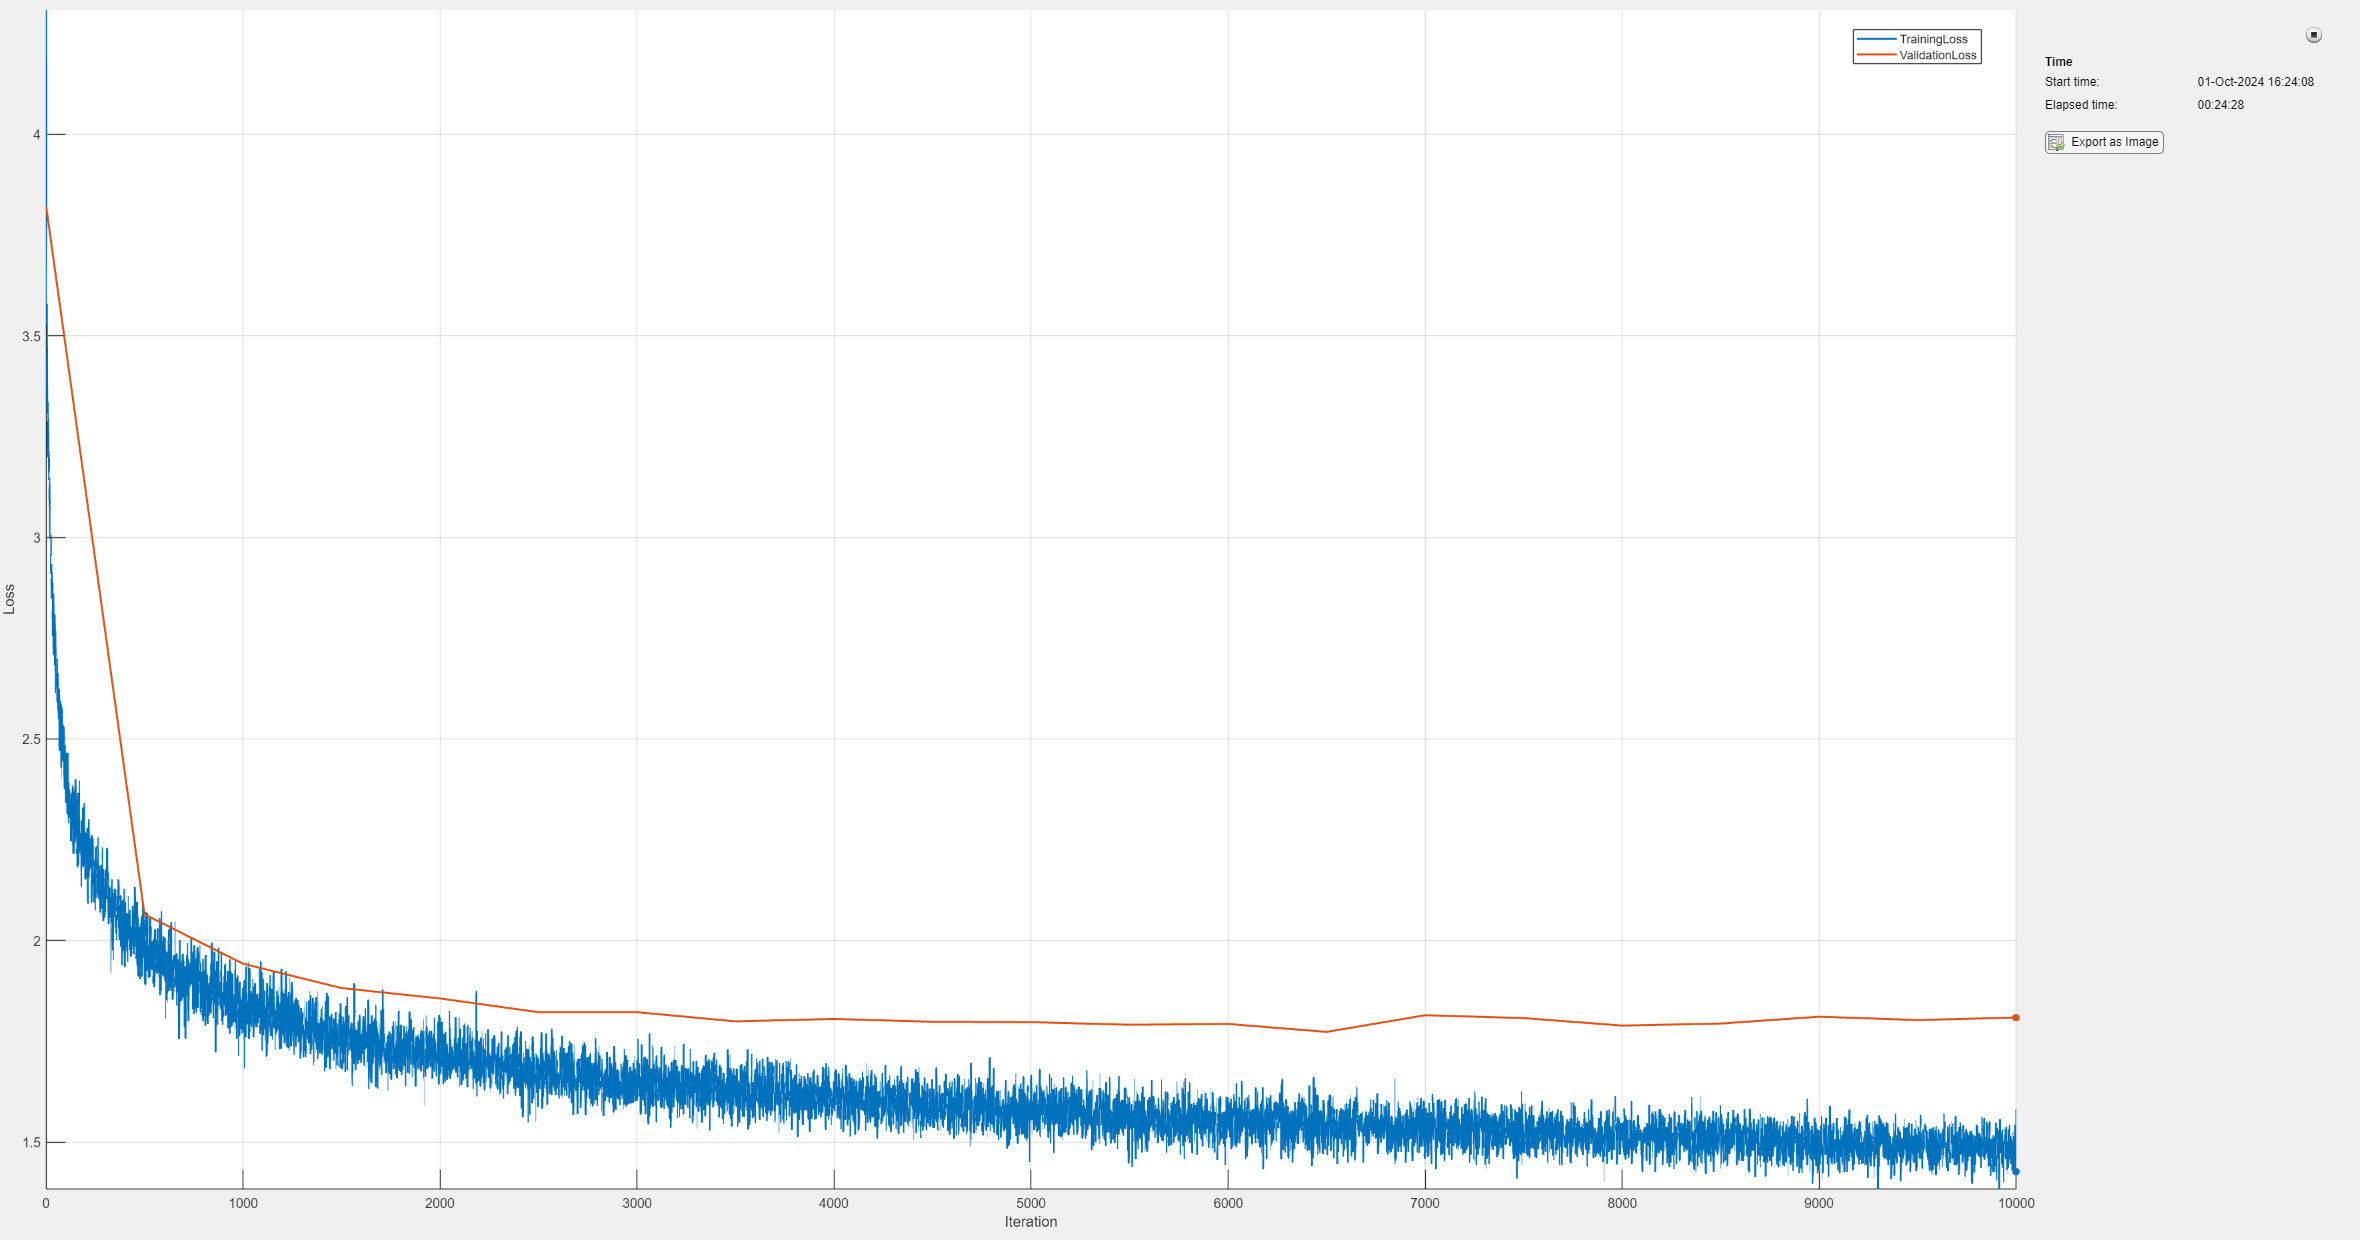

numIterations = 10000;
validationFrequency = 500;
deeperNet = nanogpt.train(deeperNet, mbqTrain, mbqValidation, ...
    LearnRate=learnRate, ...
    NumIterations=numIterations, ... 
    ValidationFrequency=validationFrequency, ...
    NumValidationIters=numValidationIters);



tbl = dsValidation.preview();
context = tbl.predictors;
disp(predictFromModel(deeperNet, context, numNewChars, tokenizer))

e.

  CIV

  No remembassa'd where kind they Muse, so death's eyes of truests.
  Making an of stormer all her,
  Me verse of you weight is leds thou have not every side white,
  For I know,
  So till seeming me,
  In seeiding were you hast of thou desire thy life?
  Making in thine decay,
  And keep.

  If they--noted.

  XCVII

  With heaven taker waste never child ta!
  The dust in the ansubsence asider self alone.
  Which thy gracious gust spirit perfeit
  Making allo'g may wrinkles are woe, 


### Build a larger model for best performance

Increase the width and depth of the network in order to train a model that performs better on the data. Add dropout to the model to reduce overfitting.

embeddingDimension = 384;
numKeyChannels = 384;
numHeads = 6;
dropout = 0.2;
numAttnBlocks = 6;

deepestNet = dlnetwork([ ...
    sequenceInputLayer(numChannels, Name="input"), ...
    wordEmbeddingLayer(embeddingDimension,tokenizer.VocabSize), ...
    additionLayer(2, Name="emb_add"), ...
    fullyConnectedLayer(tokenizer.VocabSize, Name="emb_fc")], Initialize=false);
deepestNet = deepestNet.addLayers(positionEmbeddingLayer(embeddingDimension, subsequenceLength, Name="posembed"));
deepestNet = deepestNet.connectLayers("input", "posembed");
deepestNet = deepestNet.connectLayers("posembed", "emb_add/in2");
lastLayerName = "emb_fc";

for ii = 1:numAttnBlocks
    attnBlock = attentionBlock(numHeads, numKeyChannels, tokenizer.VocabSize, ii, Dropout=dropout);
    deepestNet = deepestNet.addLayers(attnBlock);
    deepestNet = deepestNet.connectLayers(lastLayerName, "attn_sa_"+ii);
    % Create skip connections
    deepestNet = deepestNet.connectLayers(lastLayerName, "attn_add1"+ii+"/in2");
    deepestNet = deepestNet.connectLayers("attn_norm1_"+ii, "attn_add2"+ii+"/in2");
    lastLayerName = "attn_norm2_"+ii;
end

deepestNet = deepestNet.addLayers([geluLayer(Name="last_gelu"), softmaxLayer]);
deepestNet = deepestNet.connectLayers(lastLayerName, "last_gelu");
deepestNet = deepestNet.initialize();

Train the network for 30000 iterations and predict 1000 new tokens.

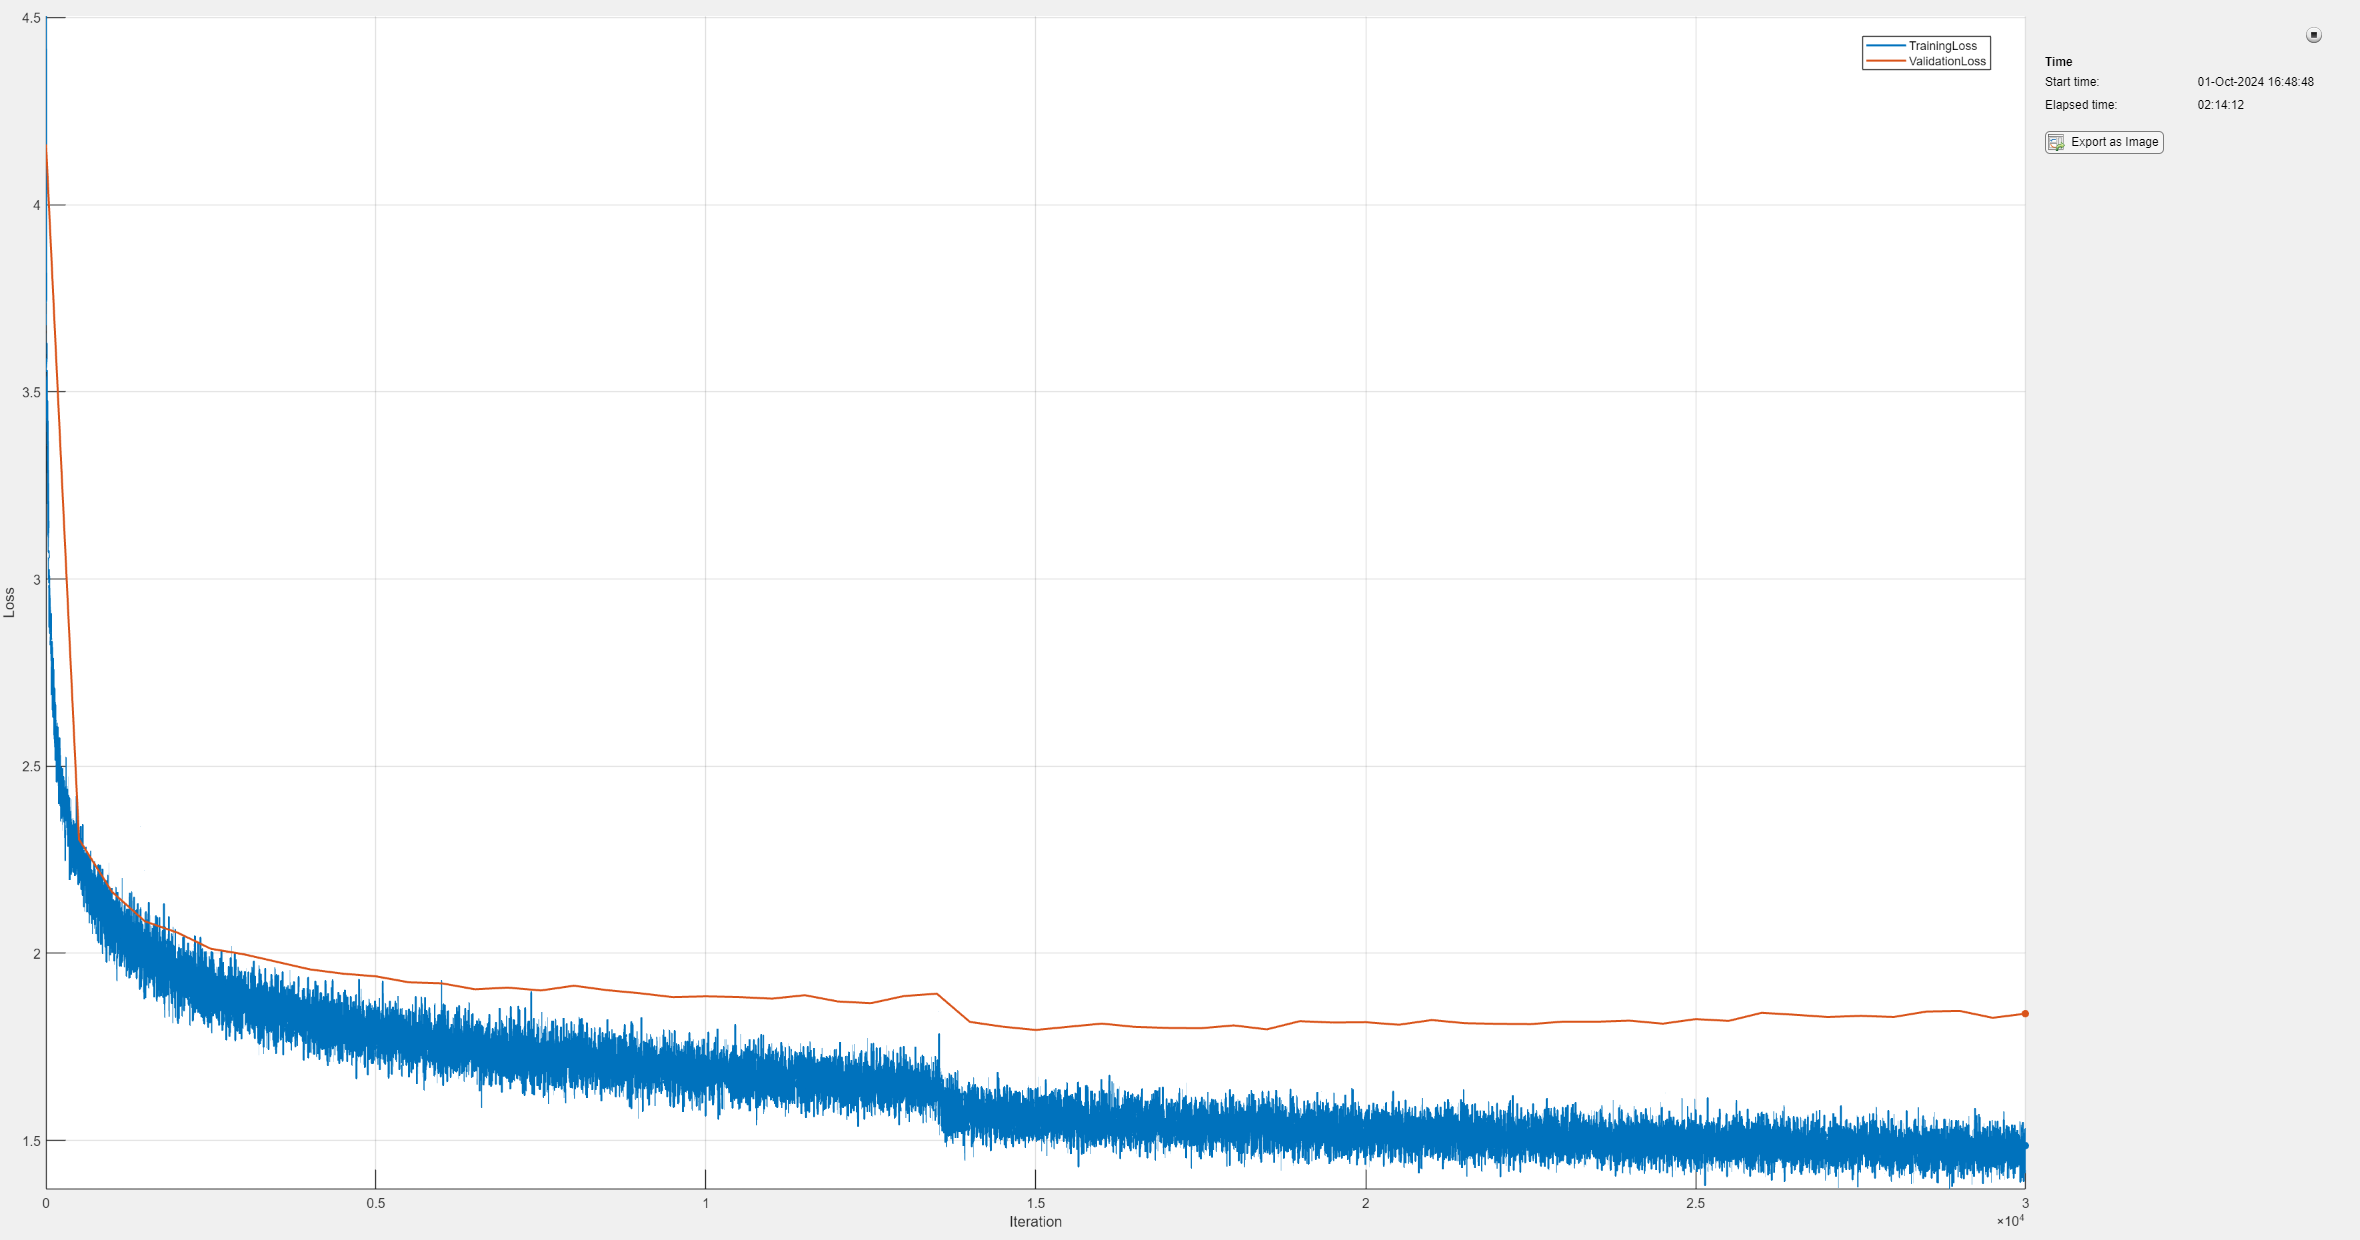

numIterations = 30000;
validationFrequency = 500;
numValidationIters = 50;
learnRate = 3e-4;
deepestNet = nanogpt.train(deepestNet, mbqTrain, mbqValidation, ...
    LearnRate=learnRate, ...
    NumIterations=numIterations, ... 
    ValidationFrequency=validationFrequency, ...
    NumValidationIters=numValidationIters);


numNewChars = 1000;
tbl = dsValidation.preview();
context = tbl.predictors;
disp(predictFromModel(deeperNet, context, numNewChars, tokenizer))

e sam who thy gyours perfecWeed hate's fill'd
  When thy liven in thy etermise.
  O'er words of writ is every grow,
  Sit, when not dull be without or endless self thee.

  X
  do their story disgrace.
     You matcheth, or desiring taken eye,
  And in this had
  And play as true life.

  CXXII

  Time,
  Do shall summer: white!
    Save gracious,
  And he so.

  CXzaz'd'd, ranch in their breath, and steel.
  For me confoan,
  Thus grow.
  What not, that lies,
  As in summerciard prais'd nim up usesty, but not love's bewelWep upon my ses of some of thou happy built, I am frost, which made, thyough thy gusts every their eye through thou with upon these doth bove you shall not breaking no did shalloses hell;
    And sofen treasure thou Wty heart;
  When wIed out advaking?
    Of sire and then this from limbs is to nopFoy so can nature though yifices of me, thou seturns thou see;
  We sweet of thy pass'd,
    My lives replete we deep feel therefore can first thou saith I badreness bormy s

function [X,T] = preprocessMinibatch(dataX, dataT)
X = cat(1, dataX{:});

T = cat(1, dataT{:});
T = onehotencode(T, 3);
end

function newChars = predictFromModel(net, context, numChars, tokenizer)
currentContext = context;
numBatches = size(context, 1);
newChars = repmat('a', [numBatches numChars]);
for ii = 1:numChars
    prediction = net.predict(currentContext,InputDataFormats="BTC",OutputDataFormats="CBT"); % CBT dlarray

    lastPrediction = prediction(:,:,end); % 1BT dlarray
    predictedToken = sampleFromLogits(lastPrediction); % 1B1 categorical
    currentContext = cat(2, currentContext(:,2:end), predictedToken);

    nextToken = squeeze(predictedToken); %B1 double
    nextChar = tokenizer.tok2char(nextToken);
    newChars(:,ii) = nextChar;
end
end

function token = sampleFromLogits(logits)
% Given a vector of probabilities, sample a token with the probability
% weight given by the elements of that vector

population = 1:size(logits,1);
numBatches = size(logits,2);
token = zeros(1,numBatches);
for ii = 1:numBatches
    token(:,ii) = randsample(population, 1, true, gather(logits(:,ii)));
end
end

function layers = attentionBlock(numHeads, numKeyChannels, vocabSize, index, opts)
arguments
    numHeads
    numKeyChannels
    vocabSize
    index
    opts.Dropout = 0
end
layers = [...
    selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal", Name="attn_sa_"+index), ...
    dropoutLayer(opts.Dropout, Name="attn_drop1_"+index), ...
    additionLayer(2, Name="attn_add1"+index), ...
    layerNormalizationLayer(Name="attn_norm1_"+index), ...
    fullyConnectedLayer(4*vocabSize, Name="attn_fc_"+index), ...
    geluLayer(Name="attn_act_"+index), ...
    dropoutLayer(opts.Dropout, Name="attn_drop2_"+index), ...
    fullyConnectedLayer(vocabSize), ...
    additionLayer(2, Name="attn_add2"+index), ...
    layerNormalizationLayer(Name="attn_norm2_"+index)];
end
